close all; clear; clc;

# Fixed Sample Rate

UpDownTestedit: up_down_test.mlx

**keywords:** 

**file created by:** {20180712, NAME}

**last updated on:** {YYYYMMDD}

**primary purpose: **Changing the number of samples taken for each phase in the fixed sample rate test to see the output data differences

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.00230439224188979;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the "servo" column was deleted beforehand

load('20180711_updown.mat');
time = UpDownTestedit(:,1);          % [sec]
ESC_us = UpDownTestedit(:,2);        % [micro sec] (this is how quickly the ESC is providing voltage to the motor -- translates to throttle% ?
Q = UpDownTestedit(:,3);             % [ft.lbf]
T = UpDownTestedit(:,4);             % [lbf]
Input_V = UpDownTestedit(:,5);       % [Volts]
Input_A = UpDownTestedit(:,6);       % [Amps]
rot_speed = UpDownTestedit(:,7);     % [rad/sec]
P_in_W = UpDownTestedit(:,8);        % [Watts]
P_out_W = UpDownTestedit(:,9);        % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;     % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;       % [ft.lbf/sec]

Motor_Eff = UpDownTestedit(:,10);    % [%]
Prop_Eff = UpDownTestedit(:,11);     % [lbf/Watts]
Overall_Eff = UpDownTestedit(:,12);  % [lbf/Watts]  
Motor_Temp = UpDownTestedit(:,13);   % [F]


## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed .* radius).^(2) .* radius);

## Plots

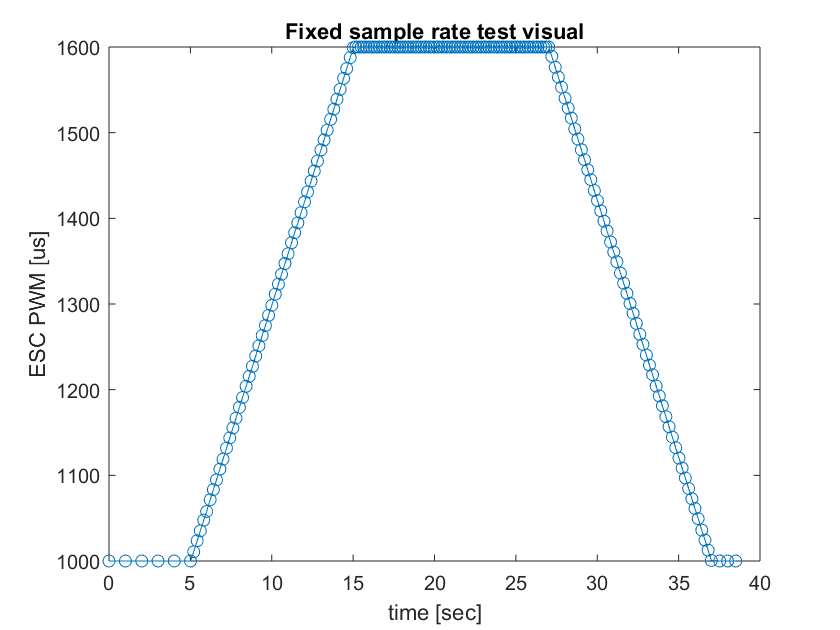

figure(1)
plot(time, ESC_us, 'o-'); title('Fixed sample rate test visual' );
xlabel('time [sec]'); ylabel('ESC PWM [us]');

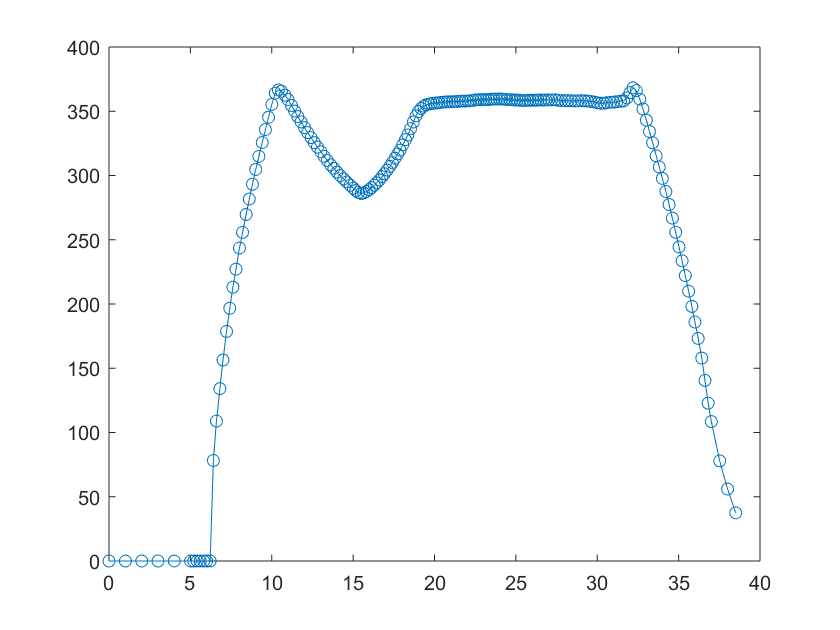




figure(2)
plot(time, rot_speed, 'o-' );